# Clean Data and Training Model:

clc;
clear all;
close all;

% Number of epochs
num_epochs = 15;

% Initialize cell arrays to store errors for all epochs
err_P_all = cell(num_epochs, 1);
err_K_all = cell(num_epochs, 1);

% Down Sampling
T_dwn = 0.2; % downsampling time
d = 0.001;
dwn_smpl_fctr = floor(T_dwn / d);

m = 2;
n = 4;
Q = eye(n);
R = eye(m);


## Load Data 

for epoch = 1:num_epochs
    % Load Data for current epoch
    data_path = sprintf("C:\\Users\\saber\\OneDrive\\Desktop\\Research\\RL LQR\\Magnetic Levitation\\Experiment\\Data DPI\\2024-07-16_14-36\\epoch %d\\workspace.mat", epoch);
    Data = load(data_path);

    S_ric = Data.S;
    K_ric = Data.K_ric;
    if epoch == 1
        K = K_ric;
    end
    % Cleaning Data and preparing for training
    state = Data.x_star;
    input = Data.u_star_noise;
    state_derivative = Data.x_star_dot;
    IXX_dot = Data.IXX_dot;
    IXU_dot = Data.IXU_dot;

    % Removing time column
    x = state(:,2:end);
    x_dot = state_derivative(:,2:5);
    IXX = IXX_dot(:,2:end);
    IXU = IXU_dot(:,2:end);


    x_iter = x(1:dwn_smpl_fctr:size(x, 1), :);
    intg_xx = IXX(1:dwn_smpl_fctr:size(IXX, 1), :);
    intg_xu = IXU(1:dwn_smpl_fctr:size(IXU, 1), :);

    % Creating x0 and x1 bar IXX and IXU
    smp_itr = size(x_iter, 1);
    x0_bar = [x_basis(x_iter(1:smp_itr-1, :)) -2*x_iter(1:smp_itr-1, :)];
    x1_bar = [x_basis(x_iter(2:smp_itr, :)) -2*x_iter(2:smp_itr, :)];
    X_diff = x1_bar - x0_bar; % eq(64 and 65)
    Ixx = intg_xx(2:smp_itr, :) - intg_xx(1:smp_itr-1, :); % eq(67)
    Ixu = intg_xu(2:smp_itr, :) - intg_xu(1:smp_itr-1, :); % eq(68)

    % Normalize the vectors
    x0_bar = x0_bar ./ vecnorm(x0_bar, 2, 2);
    x1_bar = x1_bar ./ vecnorm(x1_bar, 2, 2);
    X_diff = X_diff ./ vecnorm(X_diff, 2, 2);
    Ixx = Ixx ./ vecnorm(Ixx, 2, 2);
    Ixu = Ixu ./ vecnorm(Ixu, 2, 2);

    % DPI

    err_P = [];
    err_K = [];
    i = 1;
    % frobeniusNorm = norm(S_ric, 'fro'); % Calculate the Frobenius norm of the matrix
    % S_ric = S_ric / frobeniusNorm; % Divide each element by the Frobenius norm
    % 
    % robeniusNorm = norm(K_ric, 'fro'); % Calculate the Frobenius norm of the matrix
    % K_ric = K_ric /frobeniusNorm; % Divide each element by the Frobenius norm
    while 1
        Q_bar = Q + K' * R * K;
        Y = -Ixx * Q_bar(:); % eq(66)
        Theta = [X_diff -2*Ixx*kron(K'*R, eye(n)) -2*Ixu*kron(R, eye(n))]; % X_i in eq(62)
        is_full_rank = rank(Theta) == min(size(Theta));
        if ~is_full_rank
            display("Theta is not full rank");
        end
        p = pinv(Theta) * Y; % eq(69)
        P = P_mat(p(1:n*n)); % extract value matrix P from p
        % extract controller gain K from p
        K = p(n*n+n+1:n*n+n+n*m)'; % need to convert from vector to matrix in case of mimo system
        K = reshape(K, n, m)';
        err_P = [err_P norm(P-S_ric, 'fro')];
        err_K = [err_K norm(K-K_ric, 'fro')];
        if i >= 2
            if abs(err_P(i) - err_P(i-1)) < 0.0001 || i > 50
                break;
            end
        end
        i = i + 1;
    end

    % Store errors for current epoch in cell arrays
    err_P_all{epoch} = err_P;
    err_K_all{epoch} = err_K;
end

state=Data.x_star;
input=Data.u_star_noise;
state_derivative=Data.x_star_dot;
IXX_dot=Data.IXX_dot;
IXU_dot=Data.IXU_dot;

## **Plot the comparison result for gain and solution of Riccati **

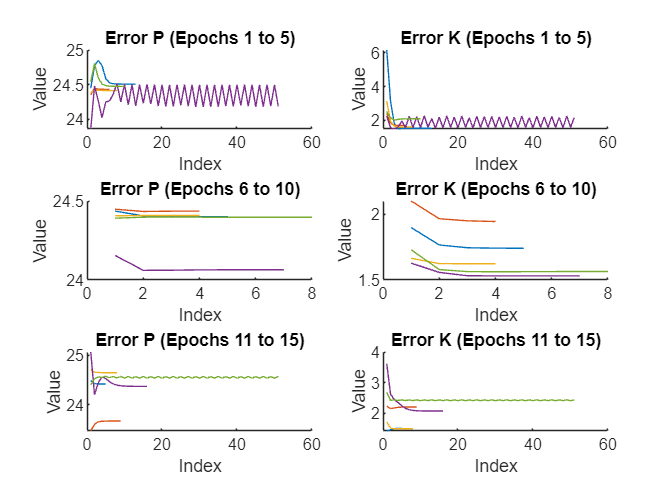

% Define the number of epochs to be grouped together
group_size = 5;

% Determine the total number of epochs
total_epochs = length(err_P_all); % Assuming err_P_all has the same length as err_K_all

% Create a figure
figure;

% Loop through each group of epochs
for start_epoch = 1:group_size:total_epochs
    end_epoch = min(start_epoch + group_size - 1, total_epochs); % Ensure end_epoch does not exceed total_epochs
    
    % Create a subplot for this group
    subplot(ceil(total_epochs / group_size), 2, (start_epoch - 1) / group_size * 2 + 1);
    hold on;
    for epoch = start_epoch:end_epoch
        plot(err_P_all{epoch});
    end
    title(sprintf('Error P (Epochs %d to %d)', start_epoch, end_epoch));
    xlabel('Index');
    ylabel('Value');
    hold off;

    % Create another subplot for the second plot (Error K)
    subplot(ceil(total_epochs / group_size), 2, (start_epoch - 1) / group_size * 2 + 2);
    hold on;
    for epoch = start_epoch:end_epoch
        plot(err_K_all{epoch});
    end
    title(sprintf('Error K (Epochs %d to %d)', start_epoch, end_epoch));
    xlabel('Index');
    ylabel('Value');
    hold off;
end

#### The code is to calculate the cost function

% Number of epochs
num_epochs = 15; % Adjust the number of epochs as needed

% Initialize a cell array to store cost values for each epoch
cost_values = cell(num_epochs, 1);
average_cost = zeros(num_epochs, 1);
last_time_step_cost = zeros(num_epochs, 1);

% Initialize a cell array to store gain matrices for each epoch
gain_matrices = cell(num_epochs, 1);


% Loop over each epoch to load data, calculate the cost function, and store the cost values
for epoch = 1:num_epochs
    % Load Data for current epoch
    data_path = sprintf("C:\\Users\\saber\\OneDrive\\Desktop\\Research\\RL LQR\\Magnetic Levitation\\Experiment\\Data DPI\\2024-07-16_14-36\\epoch %d\\workspace.mat", epoch);
    Data = load(data_path);
    
    % Extract matrices X and U from loaded data
    % Adjust according to your data structure
    X = Data.x_star(:,2:end)'; % Example extraction
    U = Data.u_star(:,2:end)'; % Example extraction

    % Extract the gain matrix for the current epoch
    gain_matrix = Data.K; % Assuming gain_matrix is the name in the data
    gain_matrices{epoch} = gain_matrix;
    
    % Number of time steps
    num_time_steps = size(X, 2);

    % Initialize array to store cost values for each time step
    cost_values_epoch = zeros(1, num_time_steps);

    % Calculate the quadratic cost function for each time step
    for t = 1:num_time_steps
        x_t = X(:, t); % Extract the state vector at time step t
        u_t = U(:, t); % Extract the control vector at time step t
        J_t = x_t' * Q * x_t + u_t' * R * u_t; % Calculate the cost at time step t
        cost_values_epoch(t) = J_t; % Store the cost value
    end
    
    % Store the cost values for the current epoch
    cost_values{epoch} = cost_values_epoch;
    
    % Calculate the average cost for the current epoch
    average_cost(epoch) = mean(cost_values_epoch);
    
    % Store the cost value for the last time step
    last_time_step_cost(epoch) = cost_values_epoch(end);
end

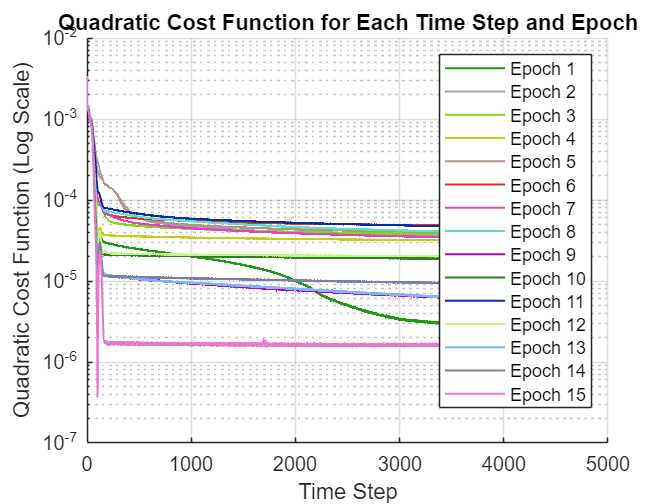


% Generate random hex color codes for each epoch
colors = rand(num_epochs, 3); % Generate random RGB colors

% Plot the cost function values for each epoch with a logarithmic scale
figure;
hold on;
for epoch = 1:num_epochs
    plot(1:length(cost_values{epoch}), cost_values{epoch}, '-', 'LineWidth', 1, 'Color', colors(epoch, :));
end
set(gca, 'YScale', 'log'); % Set the y-axis to logarithmic scale
hold off;
xlabel('Time Step');
ylabel('Quadratic Cost Function (Log Scale)');
title('Quadratic Cost Function for Each Time Step and Epoch');
legend(arrayfun(@(x) sprintf('Epoch %d', x), 1:num_epochs, 'UniformOutput', false));
grid on;

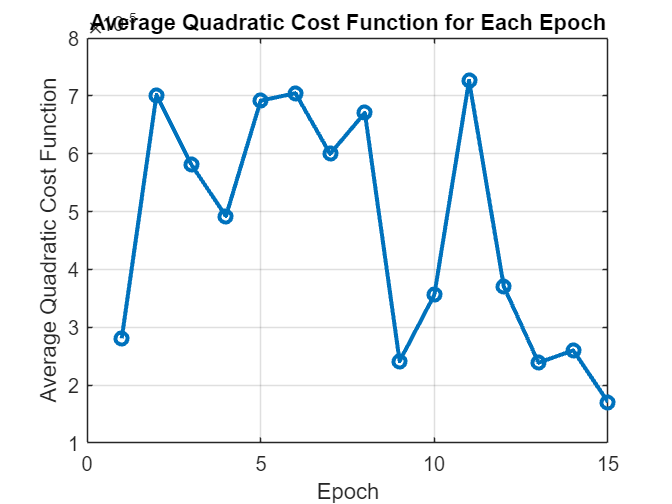


% Plot the average cost for each epoch
figure;
plot(1:num_epochs, average_cost, '-o', 'LineWidth', 2);
xlabel('Epoch');
ylabel('Average Quadratic Cost Function');
title('Average Quadratic Cost Function for Each Epoch');
grid on;

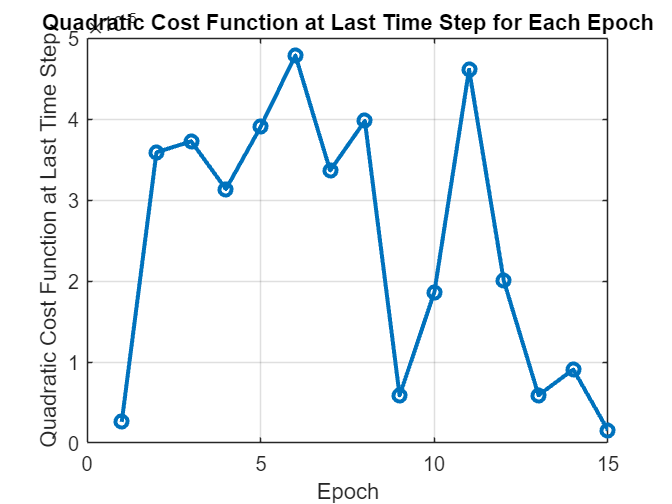


% Plot the cost for the last time step of each epoch
figure;
plot(1:num_epochs, last_time_step_cost, '-o', 'LineWidth', 2);
xlabel('Epoch');
ylabel('Quadratic Cost Function at Last Time Step');
title('Quadratic Cost Function at Last Time Step for Each Epoch');
grid on;

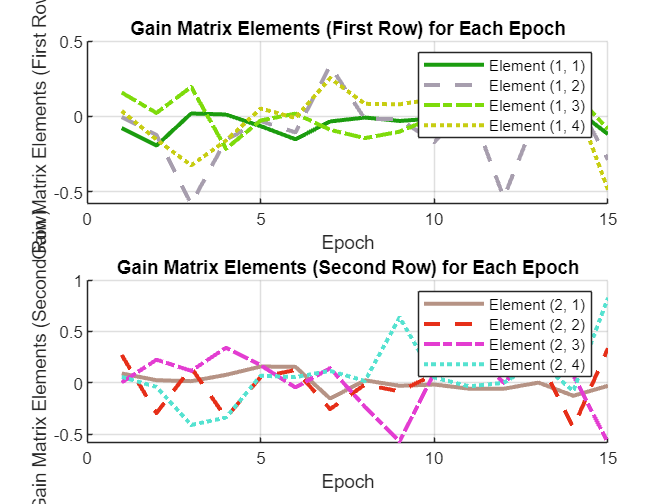


% Extract elements of gain matrices and plot them
gain_matrix_elements = zeros(num_epochs, 2, 4);
for epoch = 1:num_epochs
    gain_matrix_elements(epoch, :, :) = gain_matrices{epoch};
end

figure;

% First subplot for elements of the first row of the gain matrix
subplot(2, 1, 1);
hold on;
styles = {'-', '--', '-.', ':'}; % Different line styles for better distinction
for j = 1:4
    plot(1:num_epochs, squeeze(gain_matrix_elements(:, 1, j)), 'LineWidth', 2, 'LineStyle', styles{j}, 'Color', colors(j, :));
end
hold off;
xlabel('Epoch');
ylabel('Gain Matrix Elements (First Row)');
title('Gain Matrix Elements (First Row) for Each Epoch');
legend(arrayfun(@(x) sprintf('Element (1, %d)', x), 1:4, 'UniformOutput', false));
grid on;

% Second subplot for elements of the second row of the gain matrix
subplot(2, 1, 2);
hold on;
for j = 1:4
    plot(1:num_epochs, squeeze(gain_matrix_elements(:, 2, j)), 'LineWidth', 2, 'LineStyle', styles{j}, 'Color', colors(4+j, :));
end
hold off;
xlabel('Epoch');
ylabel('Gain Matrix Elements (Second Row)');
title('Gain Matrix Elements (Second Row) for Each Epoch');
legend(arrayfun(@(x) sprintf('Element (2, %d)', x), 1:4, 'UniformOutput', false));
grid on;


% Display the result
disp('The quadratic cost function values for each epoch are:');

The quadratic cost function values for each epoch are:


disp(cost_values);

    {[   0.0027 0.0014 0.0013 0.0013 0.0013 0.0013 0.0013 0.0013 0.0013 0.0013 0.0013 0.0013 0.0013 0.0013 0.0013 0.0013 0.0012 0.0012 0.0012 0.0012 0.0011 0.0011 0.0011 0.0011 0.0010 0.0010 9.8252e-04 9.6245e-04 9.4968e-04 9.3520e-04 9.2176e-04 9.1124e-04 9.0499e-04 8.9449e-04 8.8676e-04 8.8593e-04 8.7687e-04 8.7082e-04 8.6581e-04 8.5698e-04 8.4672e-04 8.3635e-04 8.2548e-04 8.0997e-04 7.9450e-04 7.7969e-04 7.5667e-04 7.3550e-04 7.1552e-04 6.8920e-04 6.6500e-04 6.4096e-04 6.1475e-04 5.8645e-04 5.6161e-04 5.3457e-04 5.0721e-04 4.8258e-04 4.5764e-04 4.3151e-04 4.0891e-04 3.8769e-04 3.6431e-04 3.4465e-04 3.2646e-04 3.0725e-04 2.9050e-04 2.7536e-04 2.5998e-04 2.4573e-04 2.3343e-04 2.2109e-04 2.0858e-04 1.9864e-04 1.8798e-04 1.7747e-04 1.6856e-04 1.5963e-04 1.5098e-04 1.4267e-04 1.3538e-04 1.2744e-04 1.1954e-04 1.1331e-04 1.0586e-04 9.9236e-05 9.3062e-05 8.5986e-05 7.9773e-05 7.3528e-05 6.7921e-05 6.2408e-05 5.7544e-05 5.3726e-05 4.9435e-05 4.6170e-05 4.3464e-05 4.0601e-05 3.8462e-05 3.6857

disp('The average quadratic cost function values for each epoch are:');

The average quadratic cost function values for each epoch are:


disp(average_cost);

   1.0e-04 *

    0.2809
    0.7015
    0.5814
    0.4921
    0.6917
    0.7046
    0.5997
    0.6708
    0.2414
    0.3560
    0.7266
    0.3705
    0.2388
    0.2601
    0.1707



disp('The quadratic cost function values at the last time step for each epoch are:');

The quadratic cost function values at the last time step for each epoch are:


disp(last_time_step_cost);

   1.0e-04 *

    0.0260
    0.3589
    0.3724
    0.3134
    0.3904
    0.4786
    0.3363
    0.3977
    0.0586
    0.1860
    0.4611
    0.2003
    0.0590
    0.0909
    0.0156



## **Functions**

function x_bar=x_basis(x)
%calculate basis functions
% x=[---states-->]
%   [||||||||||||]
%   [||||time||||]  
%   [||||||||||||]
n=size(x,2);%number of states of x
t=size(x,1);%time samples of x
x_bar=zeros(t,n*n);
for i=1:t
    x_bar(i,:)=kron(x(i,:),x(i,:));
end
end

function P=P_mat(p)
%Create matrix P from its vector form
n=sqrt(size(p,1));
k=1;
P=reshape(p,[n,n]);
P=(P+P')/2;
end